% import Training Data

dataSVM = Training_Dataset;

% String values to b stored as integer codes

dataSVM.Class = categorical(dataSVM.Class);
dataSVM.Class = grp2idx(dataSVM.Class);
dataSVM = table2array(dataSVM);

% Random data sampling

index = randsample(1:length(dataSVM), 1500);
train_dat = dataSVM;
train_dat(index, :) = [];
test = dataSVM(index, :);

% Achieving target points

targets = train_dat(:, end);
inputs = train_dat(:, 1:end-1);
targets_test = test(:, end);
inputs_test = test(:, 1:end-1);

% model initial train and test

model = templateSVM();
svm = fitcecoc(inputs, targets, 'Learners', model);
tstOutputs = predict(svm, inputs_test);
[c, cm] = confusion(targets_test', tstOutputs');
accuracy = sum(diag(cm))/sum(cm(:));
confusionchart(targets_test', tstOutputs');

disp(svm.CodingMatrix)

% Hyperprameters for Linear-Kernel Function %

% Linear Box constraint-1
model_lin1= templateSVM("KernelFunction", "linear", "BoxConstraint", 1);
svm_lin1 = fitcecoc(inputs, targets, 'Learners', model_lin1);
tstOutputs_lin1 = predict(svm_lin1, inputs_test);
[c_lin1, cm_lin1] = confusion(targets_test', tstOutputs_lin1');
accuracy_lin1 = sum(diag(cm_lin1))/sum(cm_lin1(:));
confusionchart(targets_test', tstOutputs_lin1');

% Linear Box constraint-100
model_lin2 = templateSVM("KernelFunction", "linear", "BoxConstraint", 100);
svm_lin2 = fitcecoc(inputs, targets, 'Learners', model_lin2);
tstOutputs_lin2 = predict(svm_lin2, inputs_test);
[c_lin2, cm_lin2] = confusion(targets_test', tstOutputs_lin2');
accuracy_lin100 = sum(diag(cm_lin2))/sum(cm_lin2(:));
confusionchart(targets_test', tstOutputs_lin2');

% Linear Box constraint-10000
model_lin3 = templateSVM("KernelFunction", "linear", "BoxConstraint", 10000);
svm_lin3 = fitcecoc(inputs, targets, 'Learners', model_lin3);
tstOutputs_lin3 = predict(svm_lin3, inputs_test);
[c_lin3, cm_lin3] = confusion(targets_test', tstOutputs_lin3');
accuracy_lin3 = sum(diag(cm_lin3))/sum(cm_lin3(:));
confusionchart(targets_test', tstOutputs_lin3');

% Hyperprameters for Polynomial-Kernel Function %

% Polynomial Box constraint-1
model_poly1 = templateSVM("KernelFunction", "polynomial", "PolynomialOrder", 3, "BoxConstraint", 10);
svm_poly1 = fitcecoc(inputs, targets, 'Learners', model_poly1);
tstOutputs_poly1 = predict(svm_poly1, inputs_test);
[c_poly1, cm_poly1] = confusion(targets_test', tstOutputs_poly1');
accuracy_poly1 = sum(diag(cm_poly1))/sum(cm_poly1(:));
confusionchart(targets_test', tstOutputs_poly1');

% Polynomial Box constraint-100
model_poly2 = templateSVM("KernelFunction", "polynomial", "PolynomialOrder", 3, "BoxConstraint", 100);
svm_poly2 = fitcecoc(inputs, targets, 'Learners', model_poly2);
tstOutputs_poly2 = predict(svm_poly2, inputs_test);
[c_poly2, cm_poly2] = confusion(targets_test', tstOutputs_poly2');
accuracy_poly2 = sum(diag(cm_poly2))/sum(cm_poly2(:));
confusionchart(targets_test', tstOutputs_poly2');

% Polynomial Box constraint-10000
model_poly3 = templateSVM("KernelFunction", "polynomial", "PolynomialOrder", 3, "BoxConstraint", 100);
svm_poly3 = fitcecoc(inputs, targets, 'Learners', model_poly3);
tstOutputs_poly3 = predict(svm_poly3, inputs_test);
[c_poly3, cm_poly3] = confusion(targets_test', tstOutputs_poly3');
accuracy_poly3 = sum(diag(cm_poly3))/sum(cm_poly3(:));
confusionchart(targets_test', tstOutputs_poly3');

% Hyperprameters for for RBF-Kernel Function %

% RBF Box constraint-1
model_rb1 = templateSVM("KernelFunction", "rbf", "BoxConstraint", 1);
svm_rb1 = fitcecoc(inputs, targets, 'Learners', model_rb1);
tstOutputs_rb1 = predict(svm_rb1, inputs_test);
[c_rb1, cm_rb1] = confusion(targets_test', tstOutputs_rb1');

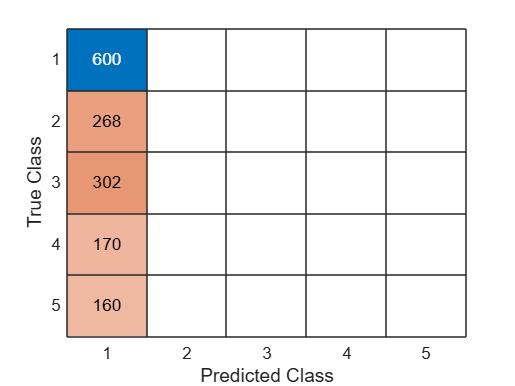

accuracy_rb1 = sum(diag(cm_rb1))/sum(cm_rb1(:));
confusionchart(targets_test', tstOutputs_rb1');